# Trabajo práctico: Filtrado digital FIR

## 2) Filtro Moving Average con señales de audio en MATLAB

### a) Cargue el archivo de audio provisto llamado Tchaikovsky.mat. En el mismo encontrará dos variables, la matriz signal con dos canales (stereo) y la variable Fs. Elija 1 de los 2 canales disponibles.

load("Tchaikovsky.mat");

### b) Agregue ruido gaussiano a esta señal tal que la relación señal-ruido entre la señal y la señal con ruido sea de 50 dB.

snr = 50;
signal_n = awgn(signal(:, 1), snr);

### c) Calcule el valor máximo de N (N_max). Determine las frecuencias fs y fco.

fco = 1e3;
N_max = round(sqrt(0.885894^2*Fs^2/fco^2 - 1));
disp(N_max);

    39



### d) Aplique el filtrado del tipo moving average a la señal con ruido para un filtro MA con dimensión igual a N = N_max. Utilice la función filter.

N = N_max;
kernel = ones(1, N) / N;
signal_f = filter(kernel, 1, signal_n);

### e) Utilice la función sound(signal_n, Fs) para reproducir las señales sin ruido, con ruido y filtrada.

sound(signal(:, 1), Fs);
pause(length(signal(:, 1))/Fs);
sound(signal_n, Fs);
pause(length(signal_n)/Fs);
sound(signal_f, Fs);
pause(length(signal_f)/Fs);

### f) Grafique la respuesta en frecuencia de las señales original y filtrada y compare. Utilice la función provista my_dft.

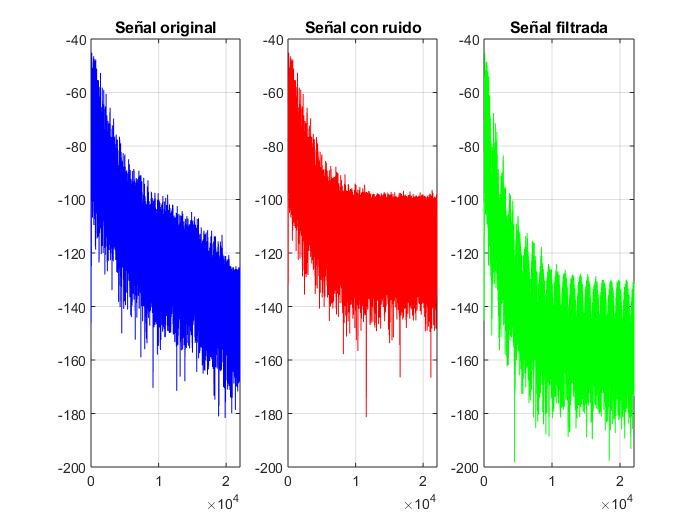

[f, dft_mag, dft_phase, dft, NFFT] = my_dft([signal(:, 1)'; signal_n'; signal_f'], Fs);

figure(1)
subplot(1, 3, 1);
plot(f, mag2db(dft_mag(:, 1)), '-b');
grid on;
title("Señal original");

subplot(1, 3, 2);
plot(f, mag2db(dft_mag(:, 2)), '-r');
grid on;
title("Señal con ruido");

subplot(1, 3, 3);
plot(f, mag2db(dft_mag(:, 3)), '-g');
grid on;
title("Señal filtrada");

### h) Repita los puntos d) a g) para N = N_max / 2 y N = N_max * 10.

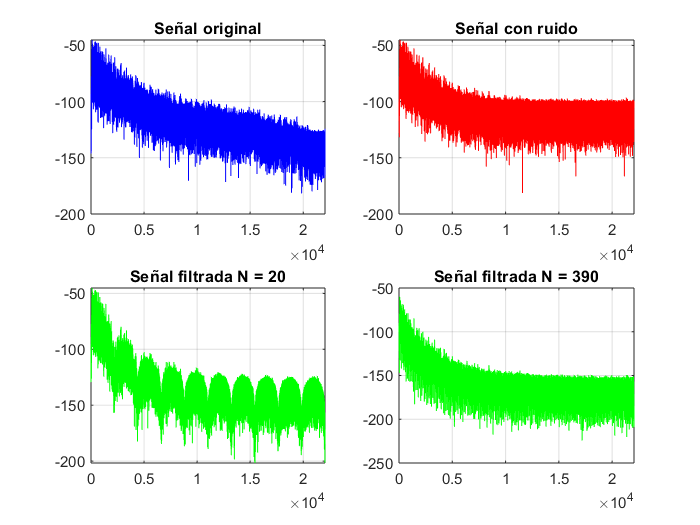

N_vect = [round(N_max/2) N_max*10];
kernel1 = ones(1, N_vect(1)) / N_vect(1);
kernel2 = ones(1, N_vect(2)) / N_vect(2);
signal_f1 = filter(kernel1, 1, signal_n);
signal_f2 = filter(kernel2, 1, signal_n);

sound(signal_f1, Fs);
pause(length(signal_f1)/Fs);
sound(signal_f2, Fs);
pause(length(signal_f2)/Fs);

clear f dft_mag dft_phase dft NFFT;
[f, dft_mag, dft_phase, dft, NFFT] = my_dft([signal(:, 1)'; signal_n'; signal_f1'; signal_f2'], Fs);

figure(2)
subplot(2, 2, 1);
plot(f, mag2db(dft_mag(:, 1)), '-b');
grid on;
title("Señal original");

subplot(2, 2, 2);
plot(f, mag2db(dft_mag(:, 2)), '-r');
grid on;
title("Señal con ruido");

subplot(2, 2, 3);
plot(f, mag2db(dft_mag(:, 3)), '-g');
grid on;
title("Señal filtrada N = " + N_vect(1));

subplot(2, 2, 4);
plot(f, mag2db(dft_mag(:, 4)), '-g');
grid on;
title("Señal filtrada N = " + N_vect(2));